# Técnicas de procesamiento de señales y datos (MUIE)

## Ejercicio práctico bloque 4.1.3. Efecto del tamaño de la FFT (v3.0)

### Objetivo

El objetivo de este ejercicio es la comprension del impacto del tamaño de la FFT en el espectro calculado de las señales. Disculpad que a veces no aparezcan tildes, pero al cambiar de version de matlab, hay un bug que no permite escribirlas.

### Desarrollo

Se dispone de una señal x(t), sinusoidal de frecuencia 1 Hz y duración de 30 periodos. Implemente un script en Matlab que realice las siguientes acciones:

- Borre variables, figuras y ventana de comandos:

clear all;
close all force;
clc;

- Genere una señal discreta x1[n] muestreando x(t) a una frecuencia de 10Hz.

f            = [ 1 ];
numPeriods   = 30;
timeDuration = numPeriods*1/f;
amplitude    = [ 1 ];
phase        = [ 0 ];
fs           = 10;
[ x, numSamples, timeIndexes ] = generateSignal(fs, timeDuration, f, amplitude, phase);

- Genere un array de tamaños de FFT desde 16 hasta 1024, incrementado cada una un factor de 2 con respecto a la anterior.

% fftSizeArray = [ 64 128 256 512 1024 2048];
fftSizeArray = 2.^(4:10) ;
numfftSizes = length(fftSizeArray);

- Dentro de un bucle for que recorra el array de tamaños de FFT, calcule el módulo de la fft (no es necesario que normalize para ver el efecto) y dibújelo usando línea continua con círculos en cada valor, y escriba en un comentario breve en el código sus observaciones y justificación, incluyendo un comentario sobre las ventajas e inconvenientes de usar tamaños de FFT grandes o pequeños. Pruebe tambien a dibujar las graficas con linea continua pero sin circulos (puede que vea mejor el efecto).

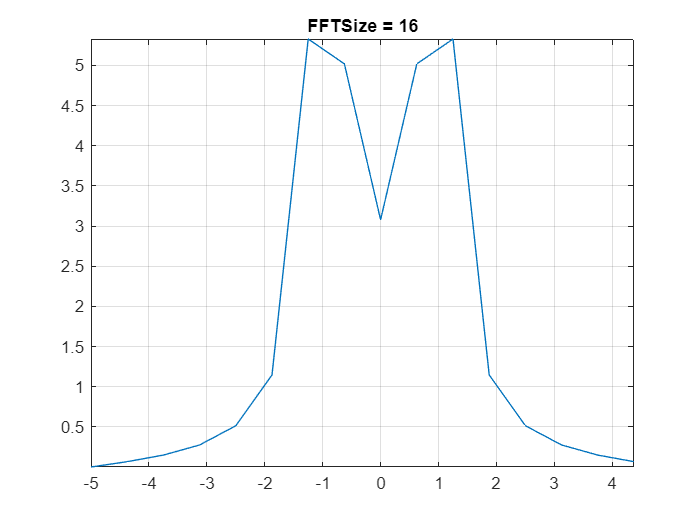

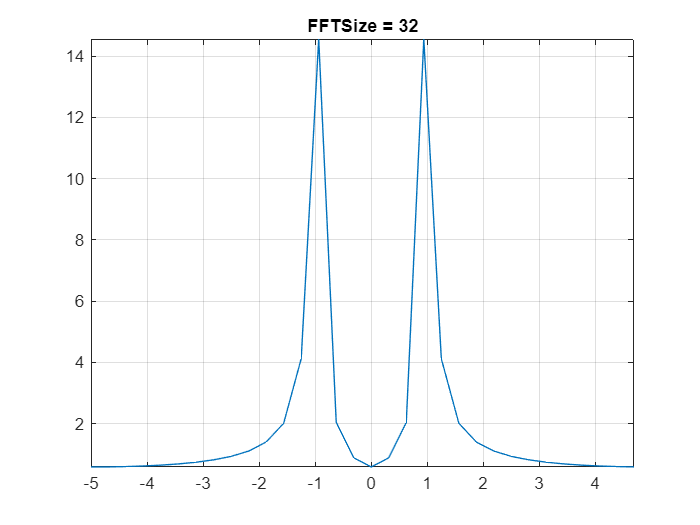

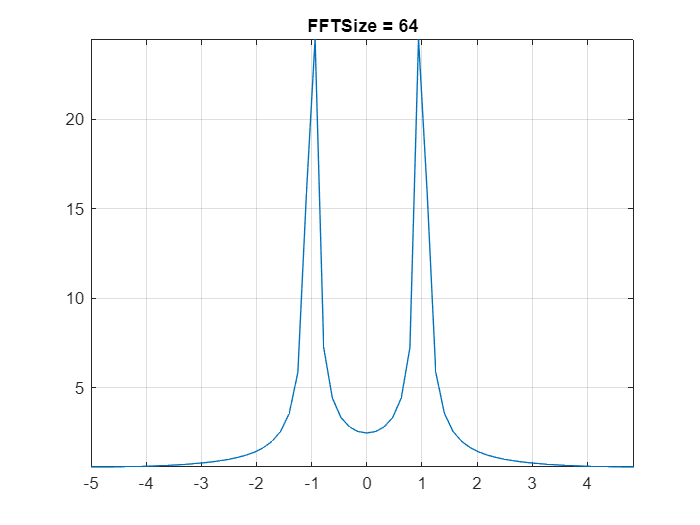

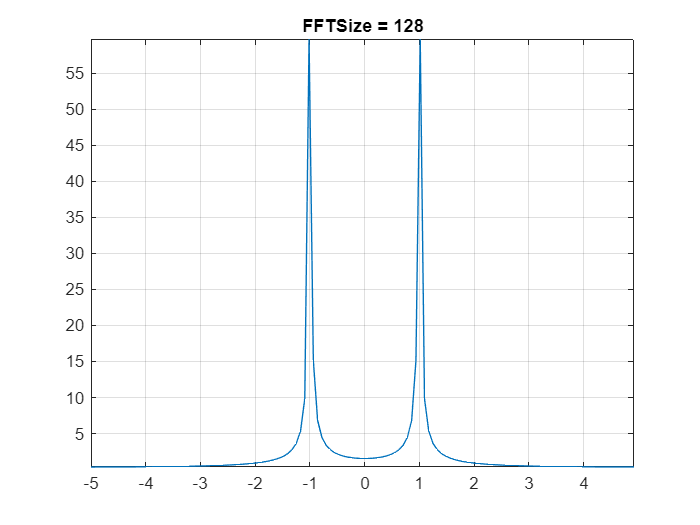

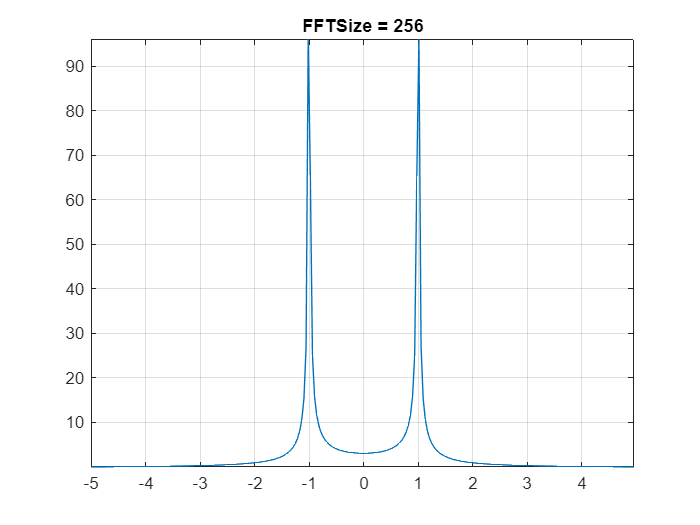

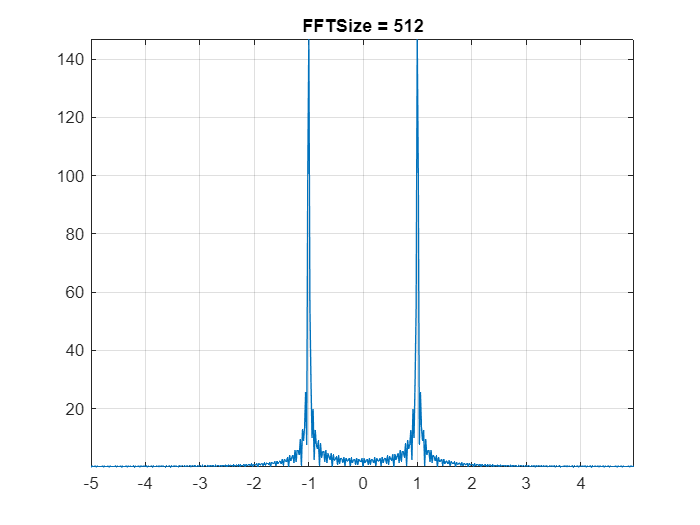

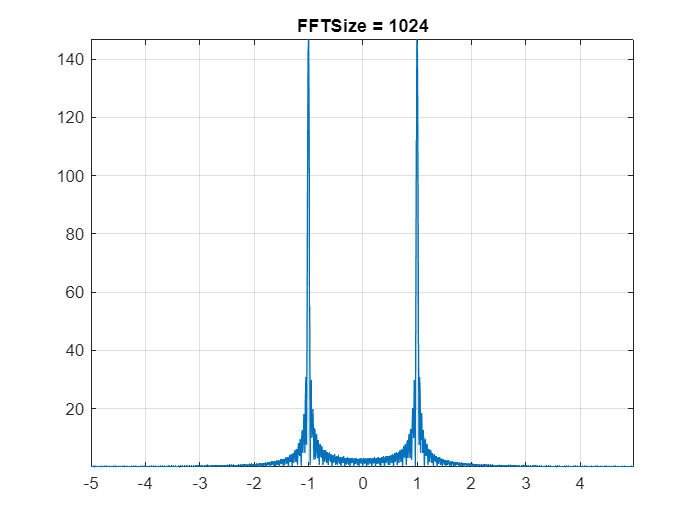

figure(numfftSizes)
for idx = 1:numfftSizes
  %  subplot(numfftSizes, idx)
  %  [fftX, frequencyIndexes] = fftPlot(x, fs, fftSizeArray(idx), '-x');
  figure;
  fftSize = fftSizeArray(idx);
  fftSize_2 = fftSize / 2;
  fftX = fft(x, fftSize); % Normalization not needed to see the effect
  fftIndexes = fs * (-fftSize_2:(fftSize_2-1)) / fftSize;
  plot(fftIndexes, abs(fftshift(fftX)), '-');
  title(['FFTSize = ', num2str(fftSizeArray(idx)) ]);
  xlim([-fs/2 fs/2]);
  grid on
  axis tight;
  %xticks(linspace(-5,5,11))
  idx;
end


% Observaciones y justificación: Describa el efecto de modificar el 
% numero de puntos de la FFT, teniendo en cuenta la teoria vista en clase
% y discuta las ventajas e inconvenientes de usar tamaños grandes o
% pequeños.

% Se sabe que por el hecho de tener que implementar una transformada con un número finito de puntos, para 
% el cálculo y el procesamiento de cantidades finitas en un ordenador, se está limitados a tener que 
% enventanar la señal original. Al implementar una ventana rectangular en el tiempo discreto, de "fftIndexes" 
% muestras en este caso, la FFT representa señales tipo sinc(x) en el dominio de la frecuencia.

% Como se discutió en el apartado anterior, dependiendo de la fs elegida
% se determinará en que puntos de esta sinc se disponen los bins de medida de la
% FFT, es decir que tan bien es representada en el espectro. 

% Sabido el comportamiento sinc, y teniendo la fs fijada, el tamaño de FFT juega
% un papel crucial en la resolución. Ya es sabido que deltaf = fs / N. 

% A N bajas, fftIndexes para este ejemplo, el deltaf es grande, 
% esto quiere decir que tenemos muy poca resolución,
% muy poca capacidad para distinguir entre valores de frecuencias
% adyacentes. Concretamente se observa una casi sinc pero con forma 
% de pico triangular de gran ancho, toda la potencia de la señal se 
% repartirá dentro de este rango. A su vez, la amplitud subestima la real,
% mientras se aumenta N, aumenta la amplitud. 

% Al aumentar el tamaño de la ventana, a su vez el pico de gran ancho comienza a
% estrecharse, como si se revelase la señal. Esto concretamente es válido 
% hasta un hipotetico N = 300, pero como se aumenta de a potencias de 2, el
% último valor que se observa este efecto es N = 256. En N = 512, 1024 (y
% eventuales superiores no simulados) se visualiza la señal sinc y sus lóbulos 
% laterales. Ahora la potencia de la señal se reparte entre el lóbulo principal
% de esa sinc (centrada en la f de la componente en particular) y sus lóbulos 
% laterales. Al aumentar el valor de N, MATLAB rellena con 0's las posiciones 
% restantes, lo que resulta en el interpolar de gráfica. 
% 
% Ahora la sinc no se estrecha, sino que aumenta la cantidad de puntos que
% se obtienen de esa misma sinc (en realidad siempre fué sinc, solo que
% antes de N 300 no la percibíamos como tal). Con N 512 obtenemos el valor 
% de amplitud en cada uno de los picos de la sinc. Sin embargo, debido a la
% interpolación (a tener aproximadamente 1 punto de medida por lobulo) los
% cruces por cero quedan enmascarados. Al duplicar N, y tener
% aproximadamente 2 puntos de medida por lóbulo, es que aparecen estos. 

% Sin embargo, esto no aumentó la capacidad de distinguir entre sí el valor
% de amplitud en el lóbulo principal o en los laterales. Si N tiende a
% infinito, no se consigue una delta perfecta, solo se toman más puntos de
% esa misma sinc de "N=300". 
% 

% Todo lo antes mencionado es válido bajo la suposición del rellenado con 
% ceros que realiza MATLAB al aumentar N. Es decir, si hacemos tender N a
% infinito no se está capturando más cantidad de periodos de la señal, se
% está rellenando con más ceros, por eso la señal luego de N=300 no 
% se estrecha más. 

% Cuando la cantidad de períodos capturados de la señal de entrada tienda 
% a infinito, es que desaparecería la sinc al estrecharse y se tendría 
% una delta en f de interes. 
% 
% 
% Por otro lado, aumentar la cantidad de períodos de señal se trata como 
% una solución de compromiso entre la capacidad de procesamiento y computo 
% disponible, en conjunto con  lo requerido por la aplicación en la que se 
% esté trabajando. 

% Es decir, en ciertas aplicaciones como el medir la amplitud de un único 
% tono a una frecuencia ya conocida, resulta una sobreinversión de recursos
% el aplicar una ventana exageradamente grande. Por más que no se logre una
% sinc lo más pequeña posible por el ordenador, con poder determinar
% con exactidud la frecuencia a la que se produce la componente de la señal
% de interés es suficiente. En contrapartida, en ciertas aplicaciones, como en 
% las telecomunicaciones, se requieren de ventanas lo suficientemente grandes
% (y del poder de calculo y computo subyacente) para satisfacer un
% determinado ancho de banda o relación señal a ruido. 